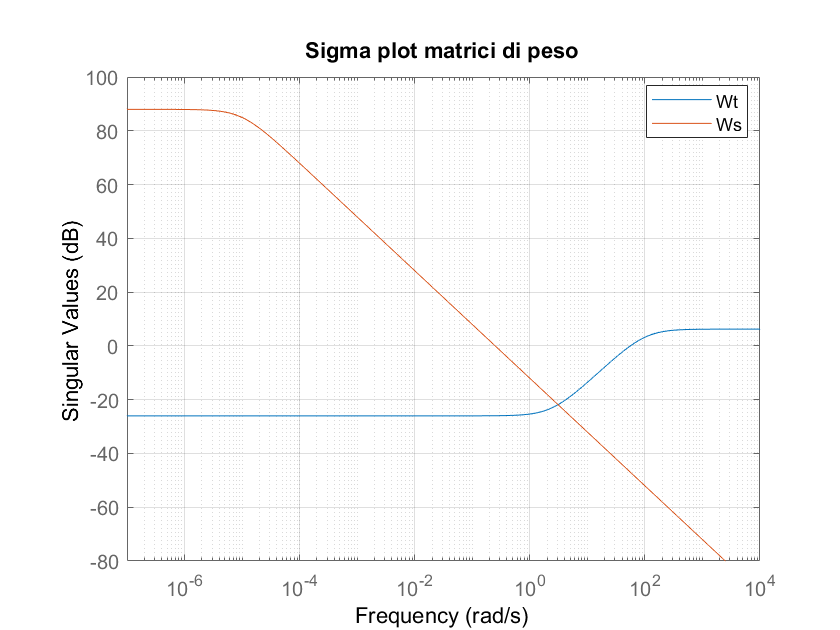

%Mixed Sensitivity (Problema standard Controllo 𝑯∞)
%aTTENZIONE: RISPETTO PRIMO CONTROLLO hINF QUESTO LO FACCIO DIRETTAMENTE
%NEL DOMINIO DELLA FREQUENZA

clear
m1=3; %massa corpo 1
m2=4; %massa carrello 2
m3=2; %massa carrello 3
m=0.2; %massa pulegga
k1=0.5; %0.5;
k2=0.5;
k3=0.5;
b2=0.4;
b3=0.4;
rm=0.2;
M=(m2+0.5*m); %M=1/(m2+0.5*m);
a=20;
g=9.81;

A=[0       1    0                  0        0    0
    -k1/m1 0  k1/m1                0        0    0
    0      0    0                  1        0    0
    k1/M   0  -(k1+k2+k3)/M   -(b2+b3)/M  k3/M  b3/M
    0      0    0                  0        0    1
    0      0    k3/m3           b3/m3    -k3/m3 -b3/m3];
B=[0            0       0
  sin(a)   sin(a)/m1    0
    0           0       0
    0           0       0
    0           0       0
    0           0       1];
C=[1 0 0 0 0 0
   0 0 1 0 0 0
   0 0 0 0 1 0];
D=[0 0 0; 0 0 0;0 0 0];

%del impianto che voglio controllare prendo solo in relazione al 2 e 3
%ingresso(forze) e 1 e 2 uscita(pos m1 e carrellino)
sys=ss(A,B(:,2:3),C(1:2,:),D(1:2,2:3));
fdt = zpk(minreal(tf(ss(A,B(:,2:3),C(1:2,:),D(1:2,2:3))),1e-5));
s = tf('s');
 Ws = 2.5e4 / (s*1e5 + 1) ;
 Wt = (1 - (1.05 * (1 - s * 0.01) / (1 + s * 0.01)));
 Wk = 0.05 ;
 sigma(Wt, Ws), grid, legend('Location','best')
title('Sigma plot matrici di peso')

 [K_infSens,CL,gamma] = mixsyn(sys,Ws,Wt,Wk);
gamma

gamma = 0.5183

L_hinf = sys * K_infSens;
S_hinf = minreal(feedback(eye(2),L_hinf));

6 states removed.


T_hinf = minreal(S_hinf * L_hinf);

15 states removed.


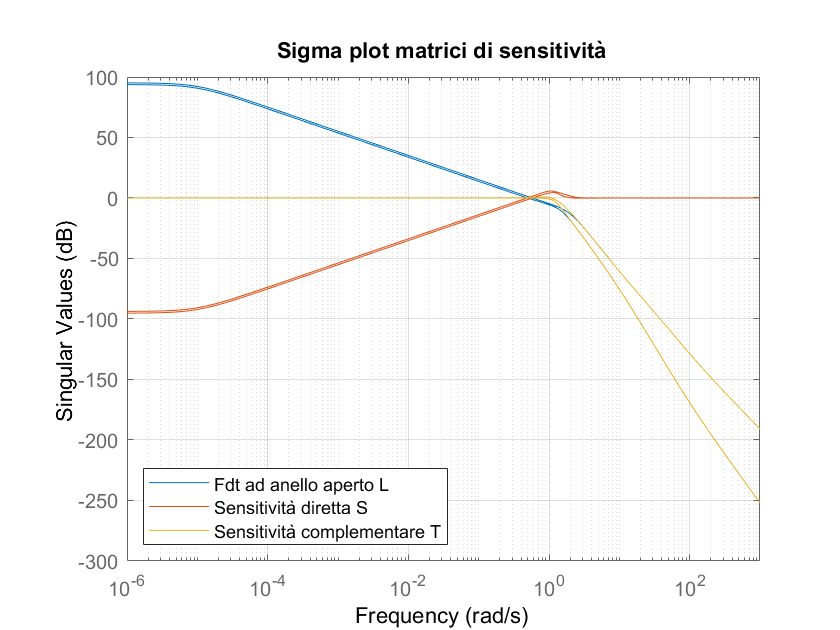

sigma(L_hinf,S_hinf,T_hinf), grid, legend('Fdt ad anello aperto L','Sensitività diretta S', ...
'Sensitività complementare T', 'location','sw')
title('Sigma plot matrici di sensitività')

[Ak,Bk,Ck,Dk]=ssdata(K_infSens);

Rt=sqrt(5e-2/3)/2/(0.3); %*1e-6
Qt=1e-3*eye(6); 

[z,p,k]=zpkdata(K_infSens);
Ws

Ws =
 
     25000
  ------------
  100000 s + 1
 
Continuous-time transfer function.

